## **D - Plot Airfoil**

Hanchen Li (hl3422@ic.ac.uk)

% Housekeeping
clear
clc
close all

%%% Airfoil Data

% AG04
AG04_data = [
    0.999999    0.000670
    0.994870    0.001167
    0.984963    0.002107
    0.973288    0.003174
    0.960910    0.004278
    0.948332    0.005403
    0.935708    0.006542
    0.923068    0.007688
    0.910423    0.008838
    0.897782    0.009989
    0.885148    0.011139
    0.872522    0.012283
    0.859901    0.013420
    0.847283    0.014552
    0.834669    0.015674
    0.822056    0.016786
    0.809443    0.017889
    0.796831    0.018980
    0.784217    0.020061
    0.771601    0.021132
    0.758985    0.022192
    0.746366    0.023242
    0.733743    0.024281
    0.721120    0.025311
    0.708496    0.026332
    0.695872    0.027342
    0.683249    0.028342
    0.670629    0.029330
    0.658010    0.030306
    0.645393    0.031267
    0.632779    0.032216
    0.620167    0.033147
    0.607557    0.034064
    0.594950    0.034963
    0.582346    0.035844
    0.569745    0.036705
    0.557147    0.037545
    0.544551    0.038364
    0.531959    0.039158
    0.519370    0.039929
    0.506783    0.040673
    0.494200    0.041391
    0.481620    0.042082
    0.469042    0.042741
    0.456467    0.043370
    0.443895    0.043967
    0.431325    0.044532
    0.418758    0.045062
    0.406195    0.045558
    0.393636    0.046016
    0.381082    0.046436
    0.368533    0.046816
    0.355990    0.047155
    0.343456    0.047449
    0.330929    0.047699
    0.318413    0.047899
    0.305908    0.048048
    0.293416    0.048143
    0.280938    0.048180
    0.268477    0.048156
    0.256036    0.048067
    0.243615    0.047906
    0.231219    0.047672
    0.218852    0.047357
    0.206516    0.046956
    0.194219    0.046460
    0.181965    0.045864
    0.169762    0.045159
    0.157618    0.044335
    0.145544    0.043381
    0.133552    0.042286
    0.121659    0.041034
    0.109883    0.039614
    0.098252    0.038005
    0.086796    0.036191
    0.075561    0.034151
    0.064602    0.031864
    0.054003    0.029317
    0.043899    0.026506
    0.034516    0.023466
    0.026187    0.020297
    0.019250    0.017178
    0.013839    0.014300
    0.009798    0.011763
    0.006815    0.009556
    0.004604    0.007625
    0.002958    0.005908
    0.001739    0.004355
    0.000861    0.002932
    0.000285    0.001613
    0.000018    0.000382
    0.000085   -0.000805
    0.000554   -0.001985
    0.001456   -0.003123
    0.002756   -0.004215
    0.004455   -0.005308
    0.006633   -0.006445
    0.009447   -0.007655
    0.013152   -0.008964
    0.018112   -0.010393
    0.024689   -0.011906
    0.032994   -0.013392
    0.042729   -0.014711
    0.053413   -0.015788
    0.064674   -0.016627
    0.076299   -0.017257
    0.088178   -0.017709
    0.100238   -0.018017
    0.112430   -0.018202
    0.124717   -0.018284
    0.137072   -0.018277
    0.149484   -0.018198
    0.161943   -0.018058
    0.174443   -0.017866
    0.186982   -0.017630
    0.199555   -0.017356
    0.212160   -0.017050
    0.224791   -0.016716
    0.237445   -0.016358
    0.250118   -0.015977
    0.262807   -0.015581
    0.275506   -0.015166
    0.288211   -0.014738
    0.300918   -0.014299
    0.313621   -0.013852
    0.326319   -0.013398
    0.339010   -0.012941
    0.351696   -0.012481
    0.364379   -0.012021
    0.377057   -0.011562
    0.389731   -0.011106
    0.402402   -0.010652
    0.415069   -0.010206
    0.427732   -0.009763
    0.440393   -0.009328
    0.453052   -0.008901
    0.465714   -0.008484
    0.478381   -0.008076
    0.491052   -0.007677
    0.503725   -0.007290
    0.516399   -0.006917
    0.529072   -0.006554
    0.541743   -0.006205
    0.554416   -0.005866
    0.567087   -0.005540
    0.579758   -0.005227
    0.592428   -0.004930
    0.605099   -0.004643
    0.617771   -0.004371
    0.630444   -0.004115
    0.643115   -0.003870
    0.655786   -0.003641
    0.668459   -0.003428
    0.681132   -0.003228
    0.693806   -0.003044
    0.706482   -0.002875
    0.719160   -0.002720
    0.731838   -0.002579
    0.744517   -0.002449
    0.757198   -0.002333
    0.769881   -0.002225
    0.782566   -0.002127
    0.795254   -0.002035
    0.807944   -0.001951
    0.820638   -0.001872
    0.833336   -0.001792
    0.846040   -0.001721
    0.858750   -0.001652
    0.871466   -0.001585
    0.884186   -0.001519
    0.896901   -0.001451
    0.909612   -0.001377
    0.922323   -0.001294
    0.935033   -0.001202
    0.947738   -0.001104
    0.960407   -0.001010
    0.972913   -0.000907
    0.984778   -0.000805
    0.994829   -0.000713
    1.000001   -0.000670
];

% x  = AG04_data(:, 1);
% y  = AG04_data(:, 2);

S3021_data = [100	0
    99.663	0.039
    98.679	0.172
    97.104	0.419
    94.996	0.769
    92.398	1.193
    89.336	1.67
    85.84	2.198
    81.959	2.776
    77.748	3.393
    73.266	4.038
    68.572	4.694
    63.73	5.341
    58.801	5.954
    53.839	6.504
    48.891	6.964
    43.996	7.312
    39.19	7.536
    34.513	7.632
    29.999	7.596
    25.685	7.433
    21.611	7.151
    17.816	6.753
    14.331	6.243
    11.182	5.631
    8.392	4.93
    5.983	4.156
    3.968	3.329
    2.358	2.472
    1.16	1.615
    0.374	0.799
    0.008	0.099
    0.191	-0.427
    0.984	-0.852
    2.32	-1.232
    4.178	-1.547
    6.542	-1.789
    9.395	-1.957
    12.712	-2.053
    16.464	-2.085
    20.614	-2.059
    25.118	-1.986
    29.928	-1.876
    34.988	-1.742
    40.237	-1.592
    45.612	-1.433
    51.047	-1.273
    56.476	-1.115
    61.834	-0.963
    67.056	-0.821
    72.079	-0.69
    76.84	-0.57
    81.283	-0.462
    85.355	-0.365
    89.005	-0.278
    92.187	-0.193
    94.876	-0.107
    97.048	-0.035
    98.66	0.003
    99.661	0.006
    100.00	0];

x  = S3021_data(:, 1) ./ 100;
y  = S3021_data(:, 2) ./ 100;

S1223_data = [100	0
99.838	0.126
99.417	0.494
98.825	1.037
98.075	1.646
97.111	2.25
95.884	2.853
94.389	3.476
92.639	4.116
90.641	4.768
88.406	5.427
85.947	6.089
83.277	6.749
80.412	7.402
77.369	8.044
74.166	8.671
70.823	9.277
67.36	9.859
63.798	10.412
60.158	10.935
56.465	11.425
52.744	11.881
49.025	12.303
45.34	12.683
41.721	13.011
38.193	13.271
34.777	13.447
31.488	13.526
28.347	13.505
25.37	13.346
22.541	13.037
19.846	12.594
17.286	12.026
14.863	11.355
12.591	10.598
10.482	9.77
8.545	8.879
6.789	7.94
5.223	6.965
3.855	5.968
2.694	4.966
1.755	3.961
1.028	2.954
0.495	1.969
0.155	1.033
0.005	0.178
0.044	-0.561
0.264	-1.12
0.789	-1.427
1.718	-1.55
3.006	-1.584
4.627	-1.532
6.561	-1.404
8.787	-1.202
11.282	-0.925
14.02	-0.563
17.006	-0.075
20.278	0.535
23.84	1.213
27.673	1.928
31.75	2.652
36.044	3.358
40.519	4.021
45.139	4.618
49.86	5.129
54.639	5.534
59.428	5.82
64.176	5.976
68.832	5.994
73.344	5.872
77.66	5.612
81.729	5.219
85.5	4.706
88.928	4.088
91.966	3.387
94.573	2.624
96.693	1.822
98.255	1.06
99.268	0.468
99.825	0.115
100	0];

% x  = S1223_data(:,1) ./ 100;
% y  = S1223_data(:,2) ./ 100;


%%% Form Airfoil

% Find leading edge
[~, idxLE] = min(x);

% Upper surface
x_upper = x(1:idxLE);
y_upper = y(1:idxLE);

% Lower surface
x_lower = x(idxLE:end);
y_lower = y(idxLE:end);

%% Make monotonic x for interpolation
xq = linspace(0,1,400);

yu = interp1(x_upper, y_upper, xq, 'linear');
yl = interp1(x_lower, y_lower, xq, 'linear');

% Camber
yc = 0.5*(yu + yl);

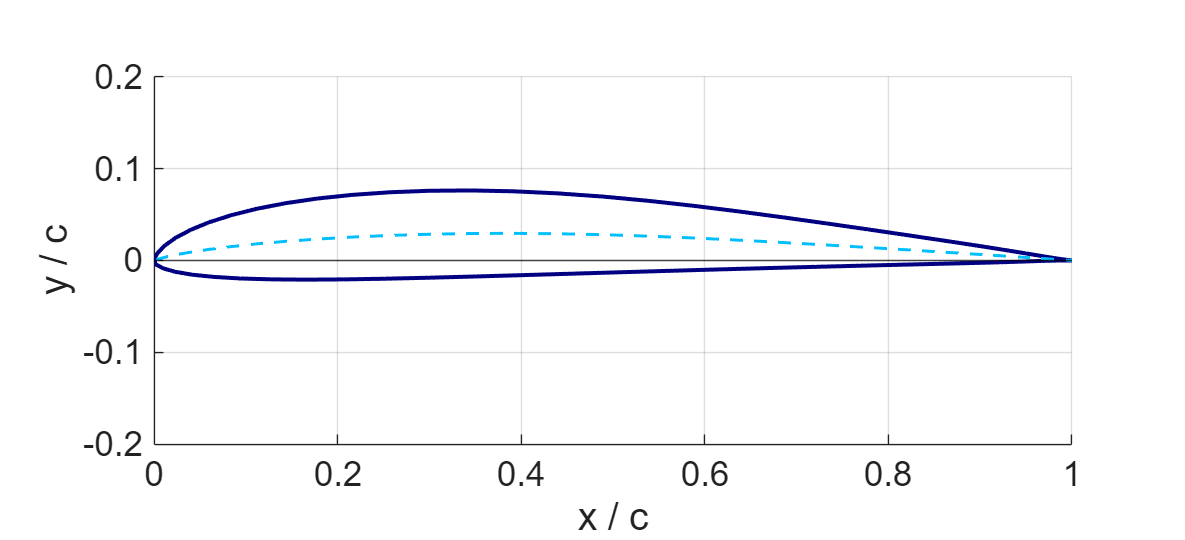

%%% Plotting
figure(1)
clf;

plot(x_upper, y_upper, '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 2);
hold on

plot(x_lower, y_lower, '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 2);
hold on

plot(xq, yc, '--', 'Color', [0/255 191/255 255/255], 'LineWidth', 1.5);
hold off

% Axis label
xlabel('x / c')
ylabel('y / c');
grid on;

% Customize axis appearance
axis equal
xlim([0 1])
ylim([-0.2 0.2])
set(gca, 'FontSize', 20.5); % Set axis font size

ax = gca;
set(ax, 'FontSize', 17.5);
set(ax, 'XAxisLocation', 'bottom');
set(ax, 'YAxisLocation', 'left');
set(ax, 'LineWidth', 0.5);
set(ax, 'Box', 'off');

yline(0, 'k-' , 'LineWidth', 0.75);   % horizontal axis at y=0

% Set figure size
set(gcf, 'Position', [0 0 790 360]);